# Comparison of closed-loop and open-loop responses

This file compares the responses and poles of the open-loop system *G(s)* with those of the closed-loop implied by the block diagram below with a range of 3 different compensators (*M=M1,  M=M2 and M=M3*) so you can compare the impact of different control strategies. You can edit these compensators and indeed the choice of system as required in the code snippets below.

The coding here is somewhat inefficient as this should make it easier for a beginner to understand what is going on. For more efficient coding with large numbers of alternative compensators see the file: ***closed_loop_compare_multiple_compensators.mlx***

We assume users are familiar with the basic analysis tools such as covered in ***plotting_with_matlab.mlx, *** ***transferfunctions_and_poles.mlx ***and ***step_responses_with_matlab.mlx.***

This live script needs the control toolbox.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Technical and mathematical background

- Enter the examples

- Analysis of closed-loop poles and damping and stability

- Manage and personalise the plotting of the step responses

- Compare open and closed-loop poles

## 1. Technical and mathematical background

Assume the following simple feedback loop.

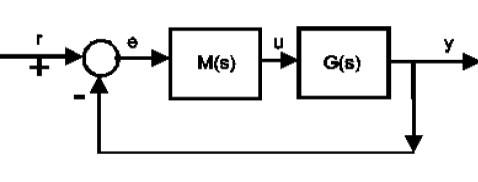

Using a standard feedback loop we have:

$Y\left(s\right)=G_c \left(s\right)R\left(s\right)$ with   $G_c =\frac{\textrm{GM}}{1+\textrm{GM}}$

$U\left(s\right)=G_{\textrm{cu}} \left(s\right)R\left(s\right)$ with   $G_{\textrm{cu}} =\frac{M}{1+\textrm{GM}}$

$E\left(s\right)=G_{\textrm{ce}} \left(s\right)R\left(s\right)$ with   $G_{\textrm{ce}} =\frac{1}{1+\textrm{GM}}$

The code below will generate all the transfer functions and then the corresponding step responses before creating the plots manually to ensure these are clear and easy to read.

- Section 2 creates the closed-loop transfer functions for each compensator (M=M1,  M=M2 and M=M3).

- Section 3 Analyses the behaviours

- Section 4 produces a plot overlaying the step responses (outputs, inputs and errors).

- Section 5 computes and overlays the closed-loop poles and zeros.

To run a different example, change the data in lines 1-4 and re-run the whole file.

## 2. Enter the examples 

The default code uses these mumbers.

$G\left(s\right)=\frac{1}{s^2 +5s+6};\;\;\textrm{M1}=1;\;\;\textrm{M2}\left(s\right)=\frac{4}{s}$;  $\textrm{M3}=\frac{6s+8}{s}$

Modify the code in lines 1-4 below for different examples.

#### Create these objects in MATLAB as follows

G=tf(1,[1 5 6])

G =
 
        1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.



M1=6

M1 = 6

M2=tf(4,[1 0]) %%% Simple integral

M2 =
 
  4
  -
  s
 
Continuous-time transfer function.



M3=tf([6,8],[1 0]) %% PI

M3 =
 
  6 s + 8
  -------
     s
 
Continuous-time transfer function.



% Alternative example
%G=tf(0.5,[1 2 1]); M1=1;  M2=4; M3=tf([1 5],[1 1]);

#### Create the closed-loop transfer functions for each compensator

Gc1=feedback(G*M1,1)

Gc1 =
 
        6
  --------------
  s^2 + 5 s + 12
 
Continuous-time transfer function.



Gcu1=feedback(M1,G)

Gcu1 =
 
  6 s^2 + 30 s + 36
  -----------------
   s^2 + 5 s + 12
 
Continuous-time transfer function.



Gce1=feedback(1,G*M1)

Gce1 =
 
  s^2 + 5 s + 6
  --------------
  s^2 + 5 s + 12
 
Continuous-time transfer function.



Gc2=feedback(G*M2,1)

Gc2 =
 
            4
  ---------------------
  s^3 + 5 s^2 + 6 s + 4
 
Continuous-time transfer function.



Gcu2=feedback(M2,G)

Gcu2 =
 
    4 s^2 + 20 s + 24
  ---------------------
  s^3 + 5 s^2 + 6 s + 4
 
Continuous-time transfer function.



Gce2=feedback(1,G*M2)

Gce2 =
 
    s^3 + 5 s^2 + 6 s
  ---------------------
  s^3 + 5 s^2 + 6 s + 4
 
Continuous-time transfer function.



Gc3=feedback(G*M3,1)

Gc3 =
 
         6 s + 8
  ----------------------
  s^3 + 5 s^2 + 12 s + 8
 
Continuous-time transfer function.



Gcu3=feedback(M3,G)

Gcu3 =
 
  6 s^3 + 38 s^2 + 76 s + 48
  --------------------------
    s^3 + 5 s^2 + 12 s + 8
 
Continuous-time transfer function.



Gce3=feedback(1,G*M3)

Gce3 =
 
    s^3 + 5 s^2 + 6 s
  ----------------------
  s^3 + 5 s^2 + 12 s + 8
 
Continuous-time transfer function.





disp('END OF SECTION 2')

END OF SECTION 2


## **3. Analysis of closed-loop poles and damping and stability**

- Stable if all poles are in LHP.

- Implied time constant is -1/(real(pole)). Settling time is approximately 3 time constants.

- System under-damped with complex poles. Typically damping acceptable if the real part is larger than the imaginary part and not otherwise. For precise criteria see analysis of 2nd order systems notes.

disp('Closed-loop poles for G and M1')

Closed-loop poles for G and M1


p1 = pzmap(Gc1)

p1 =   -2.5000 + 2.3979i
  -2.5000 - 2.3979i


disp('Closed-loop poles for G and M2')

Closed-loop poles for G and M2


p2 = pzmap(Gc2)

p2 =   -3.6590 + 0.0000i
  -0.6705 + 0.8023i
  -0.6705 - 0.8023i


disp('Closed-loop poles for G and M3')

Closed-loop poles for G and M3


p3 = pzmap(Gc3)

p3 =   -2.0000 + 2.0000i
  -2.0000 - 2.0000i
  -1.0000 + 0.0000i


**Steady-state offset (FVT we can use MATLAB albeit slightly clumsy)**

disp('Closed-loop offset for G and M1')

Closed-loop offset for G and M1


offset1 = dcgain(Gce1)

offset1 = 0.5000

disp('Closed-loop offset for G and M2')

Closed-loop offset for G and M2


offset2 = dcgain(Gce2)

offset2 = 0

disp('Closed-loop offset for G and M3')

Closed-loop offset for G and M3


offset3 = dcgain(Gce3)

offset3 = 0

**Step responses using simple MATLAB defaults**

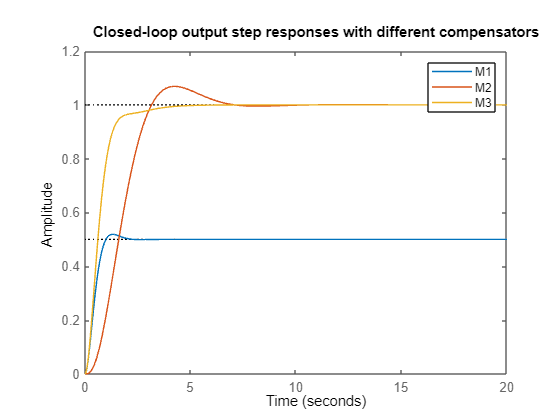

runtime=20;
step(Gc1,Gc2,Gc3,runtime); legend('M1','M2','M3')
title('Closed-loop output step responses with different compensators')

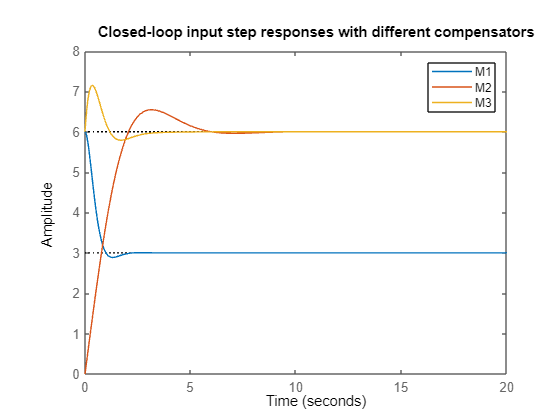

step(Gcu1,Gcu2,Gcu3,runtime); legend('M1','M2','M3')
title('Closed-loop input step responses with different compensators')


disp('END OF SECTION 3')

END OF SECTION 3


## 4. Manage and personalise the plotting of the step responses

This section shows how you can personalise the output plots for inclusion in a report or other requirements. For simplicty the code computes the step responses for each compensator on a fixed time scale determined by MATLAB (line 43) as appropriate for the open-loop system, but you can set the desired end time for the simulations manually if you desire.

#### Open-loop step response

[yo,t] = step(G);
uo = (t>0);

#### Numerical values for closed-loop step responses for error, output and input.

y1 = step(Gc1,t);
y2 = step(Gc2,t);
y3 = step(Gc3,t);
u1 = step(Gcu1,t);
u2 = step(Gcu2,t);
u3 = step(Gcu3,t);
e1 = step(Gce1,t);
e2 = step(Gce2,t);
e3 = step(Gce3,t);

The code below overlays the responses for the open-loop and the alternative compensators using different figures for input, ouput and error.

**Output figures**

figure(1)
subplot(311)
plot(t,yo,'r',t,y1,'b:',t,y2,'g--',t,y3,'m-.')
title('Output responses')
legend('Open-loop','Closed-loop (M1)','Closed-loop (M2)','Closed-loop (M3)','Location','southeast')


**Input figures**

subplot(312)
plot(t,uo,'r',t,u1,'b:',t,u2,'g--',t,u3,'m-.')
title('Input responses')
legend('Open-loop','Closed-loop (M1)','Closed-loop (M2)','Closed-loop (M3)','Location','southeast')

**Error/offset figures**

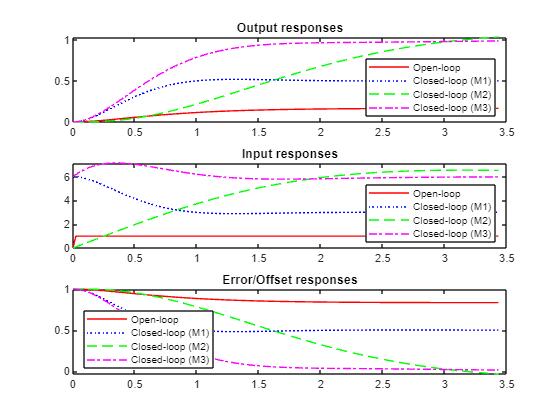

subplot(313)
plot(t,1-yo,'r',t,e1,'b:',t,e2,'g--',t,e3,'m-.')
title('Error/Offset responses')
legend('Open-loop','Closed-loop (M1)','Closed-loop (M2)','Closed-loop (M3)','Location','southwest')


disp('END OF SECTION 4')

END OF SECTION 4


## 5. Compare open and closed-loop poles

The poles can be computed using the pzmap file, but in order to overlay, it is necessary to control the plotting manually as shown below.

#### Compute the poles

po=pzmap(G)

po =    -3.0000
   -2.0000


p1 = pzmap(Gc1)

p1 =   -2.5000 + 2.3979i
  -2.5000 - 2.3979i


p2 = pzmap(Gc2)

p2 =   -3.6590 + 0.0000i
  -0.6705 + 0.8023i
  -0.6705 - 0.8023i


p3 = pzmap(Gc3)

p3 =   -2.0000 + 2.0000i
  -2.0000 - 2.0000i
  -1.0000 + 0.0000i


#### Plot the poles on an Argand diagram

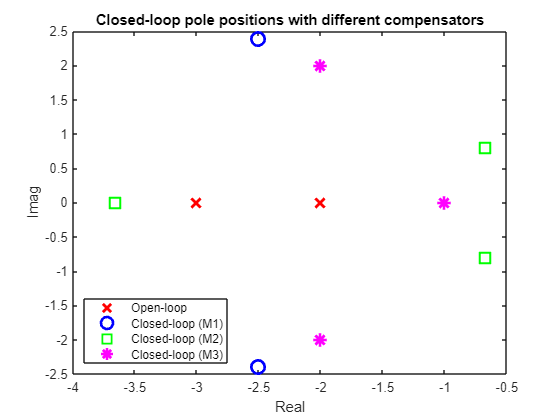

figure(2); clf
plot(real(po),imag(po),'rx','markersize',10,'linewidth',2);hold on
plot(real(p1),imag(p1),'bo','markersize',10,'linewidth',2);
plot(real(p2),imag(p2),'gs','markersize',10,'linewidth',2);
plot(real(p3),imag(p3),'m*','markersize',10,'linewidth',2);
title('Closed-loop pole positions with different compensators')
legend('Open-loop','Closed-loop (M1)','Closed-loop (M2)','Closed-loop (M3)','Location','southwest')
xlabel('Real');
ylabel('Imag')